# Linear Control Design II - Group Work Problem Module 6 

clear

## Description

Figure 1 shows an aircraft in lateral motion where the movements are yaw (rotation around the vertical axis) and roll (rotation around the longitudinal axis). The lateral motion of an aircraft takes primarily place in the horizontal plane. 

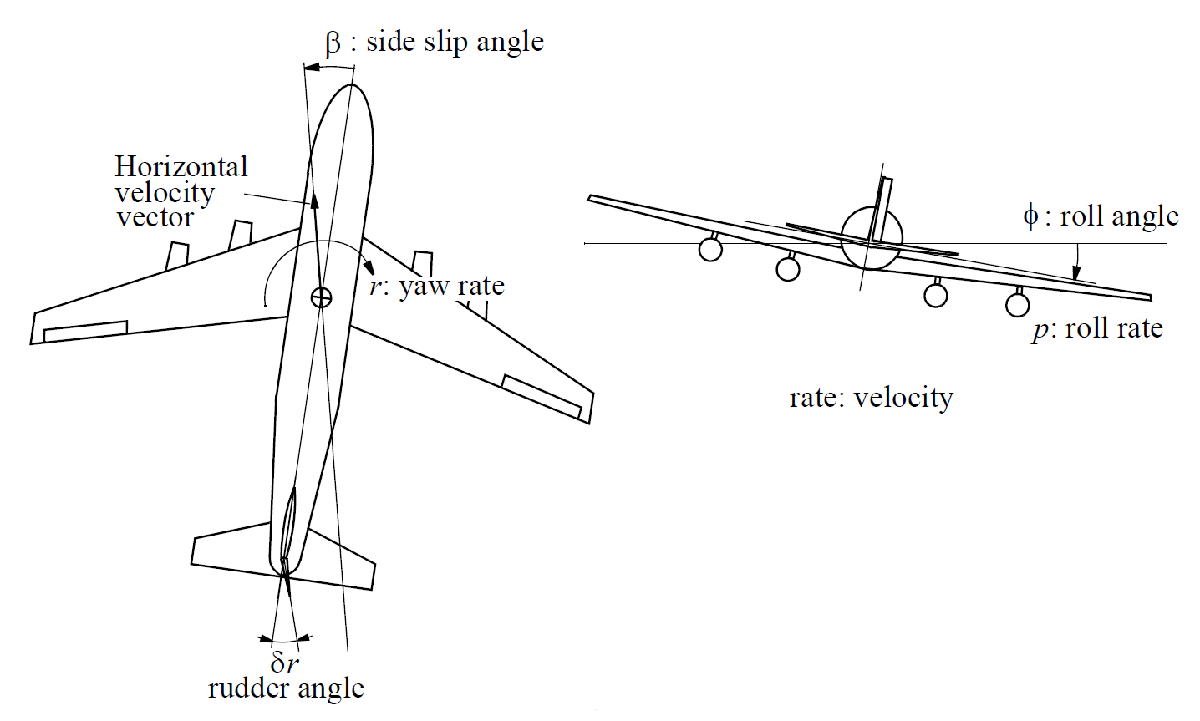  

			Figure 1: Lateral dynamics of a Boeing 747

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:

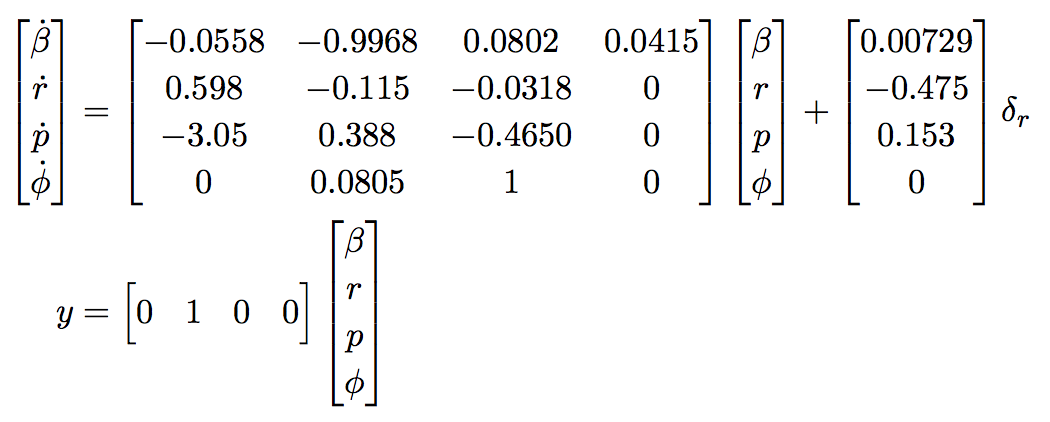

where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), and $\delta_r$ is the rudder deflection (rad). 

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =       -0.0558      -0.9968       0.0802       0.0415
        0.598       -0.115      -0.0318            0
        -3.05        0.388       -0.465            0
            0       0.0805            1            0


B = [0.00729; -0.475; 0.153; 0]

B =       0.00729
       -0.475
        0.153
            0


C = [0 1 0 0]

C =      0     1     0     0


D = 0;

This assignment guides you through the analysis of the aircraft’s lateral dynamics in terms of natural modes and system responses to non-zero initial conditions and external inputs. 

**Problem 1** Calculate the eigenvalues of the system dynamical matrix A, and based on those identify, if relevant, the time constants, natural frequencies and damping ratios. 

% Your solution goes here:
[M,L] = eig(A);
eigs = diag(L)

eigs =     -0.032935 +    0.94665i
    -0.032935 -    0.94665i
     -0.56265 +          0i
    -0.007278 +          0i


realEigs = eigs(imag(eigs)==0);
complexEigs = eigs(imag(eigs)~=0);
eigPairs = eigs(imag(eigs)>0);

tau = -1./realEigs;
w_n = abs(eigPairs);
zeta_n = -real(eigPairs)./w_n;

display(tau),display(w_n),display(zeta_n)

tau =        1.7773
        137.4


w_n =       0.94723


zeta_n =       0.03477


**Problem 2** Based on the calculated eigenvalues determine the natural modes (also known as eigenmodes) of the system and plot their temporal evolution as time goes to infinitiy.

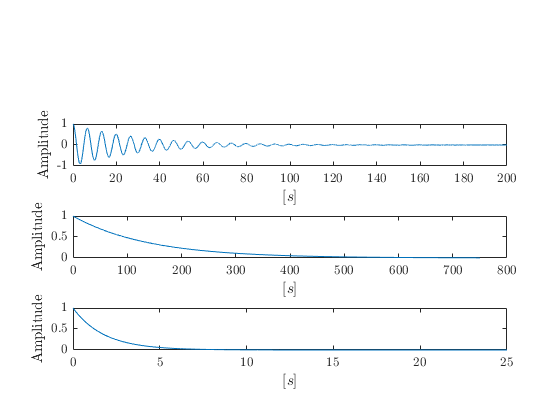

% Your solution goes here:
t = 0:0.01:1000;
figure
numReal = length(realEigs);
numPairs = length(eigPairs);
t_plot = [2501, 75001, 20001];
for i = 1:numReal
    subplot(size(A,1),1,size(A,1)+1-i)
    plot(t(1:t_plot(i)),exp(realEigs(i)*t(1:t_plot(i))))
    xlabel('$[s]$')
    ylabel('Amplitude')
end
for i = 1:numPairs
    j = i+numReal;
    subplot(size(A,1),1,size(A,1)+1-j)
    plot(t(1:t_plot(j)),real(exp(eigPairs(i)*t(1:t_plot(j)))))
    xlabel('$[s]$')
    ylabel('Amplitude')
end

display(M)

M =       0.19937 -    0.10627i      0.19937 +    0.10627i    -0.017178 +          0i    0.0067218 +          0i
    -0.077977 -    0.13326i    -0.077977 +    0.13326i    -0.011828 +          0i     0.040422 +          0i
    -0.016547 +    0.66677i    -0.016547 -    0.66677i     -0.48953 +          0i    -0.010525 +          0i
      0.69301 +          0i      0.69301 +          0i      0.87174 +          0i       0.9991 +          0i


The eigenstructure of the lateral dynamics is usually represented by two real eigenvalues and one pair of complex conjugate eigenvalues. The three lateral modes are referred to as ***roll subsidence***, ***spiral*** and ***dutch roll***. 

- The **roll subsidence** **mode** is non-oscillatory and is usually decoupled from the spiral mode and from the dutch roll modes. In rolling motion the wing experiences a component of velocity normal to the wing resulting in a small increase in the angle of attack on the down- going wing and a small decrease on the up-going wing thus, generating a lift difference over the wing span. Moreover, the lift difference gives rise to a restoring roll moment represented by the roll subsidence mode. 

- The **spiral mode** is usually slow non-oscillatory and involves complex coupled motion in roll, yaw and side-slip angle. The spiral mode is usually excited by a disturbance in side-slip which is typically followed by a disturbance in roll. The side-slip angle generates a force on the tail fin, which in turn generates a yawing moment in the direction of the side-slip angle. The yawing motion generates increased differential lift across the wing span inducing increased roll moment and thereby, aggravates the situation. 

- The** dutch roll mode** is a damped oscillation and the motion is a complex interaction between the three lateral degrees of freedom. The dutch roll mode makes the wing tip move in an elliptic pattern seen from the side parallel to the wing. 

**Problem 3** Based on the found eigenvalues and the aforementioned modes, associate the eigenvalues to the corresponding mode of the lateral dynamics. 	

% Your solution goes here:

The complex eigenvalue pair corresponds to the dutch roll mode (damped oscillation) 

display(complexEigs)

complexEigs =     -0.032935 +    0.94665i
    -0.032935 -    0.94665i


The larger of the two real eigenvalues corresponds to the roll subsidence mode (non-oscillatory)

display([realEigs(1) tau(1)]), 

     -0.56265       1.7773



The larger of the two real eigenvalues corresponds to the spiral mode (**slow** non-oscillatory)

display([realEigs(2) tau(2)]), 

    -0.007278        137.4



**Problem 4** Compute the modal matrix $\mathbf{M}_{lat}$of the system and discuss which natural modes contributes most and least to the dynamics of the state variables $\beta, r, p, \varphi$ (Make sure that your modal matrix has real elements)	

% Your solution goes here:
[Mreal, ~] = cdf2rdf(M,L)

Mreal =       0.19937     -0.10627    -0.017178    0.0067218
    -0.077977     -0.13326    -0.011828     0.040422
    -0.016547      0.66677     -0.48953    -0.010525
      0.69301            0      0.87174       0.9991


$\beta$ gets the largest contribution from the dutch roll mode and the least from the spiral mode

$r$ gets the largest contribution from the dutch roll mode and the least from the roll subsidence mode

$p$ gets the largest contribution from the dutch roll and roll subsidence modes

$\varphi$ gets the largest contribution from the spiral mode, although with significant contributions from the other modes.

**Problem 5** Determine the transfer function from rudder deflection $\delta_r$ to yaw rate r, and calculate the Bode’s diagram. Which of the aforementioned modes are visible in the magnitude response of the Bode’s diagram? 		

% Your solution goes here:
sys_ss = ss(A,B,C,D);
G = tf(sys_ss)


G =
 
     -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
  ---------------------------------------------------
  s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



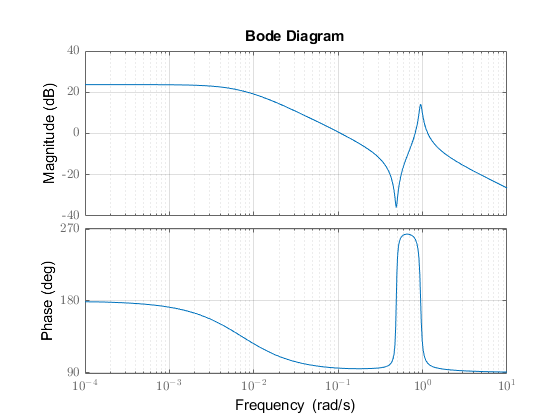

figure
bode(G)
grid on

**Problem 6** Calculate the zero-state response for a step of 5 degrees in the rudder input. Analyse the response in connection with the modal analysis. 	

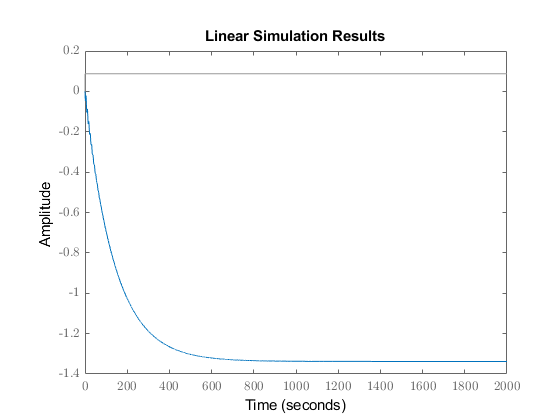

% Your solution goes here:
x0 = [0 0 0 0];
t = 0:0.1:2000;
u = ceil(t/2000)*5*pi/180;
lsim(sys_ss,u,t,x0)

**Problem 7** Calculate the zero-input response for a side-slip initial angle $\beta_0 = 1$degree. Analyse the response in connection with the modal analysis. 	

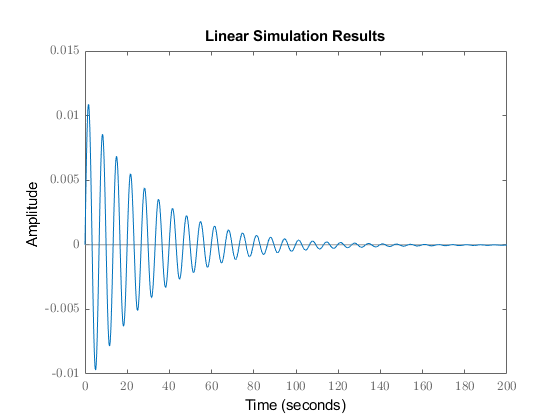

% Your solution goes here:
t = 0:0.1:200;
u = t*0;
x0 = [pi/180 0 0 0];
lsim(sys_ss,u,t,x0)

**Problem 8** Calculate the zero-state response for the rudder deflection shown in the figure below and discuss the aircraft’s dynamical behaviour during these manoeuvres. 

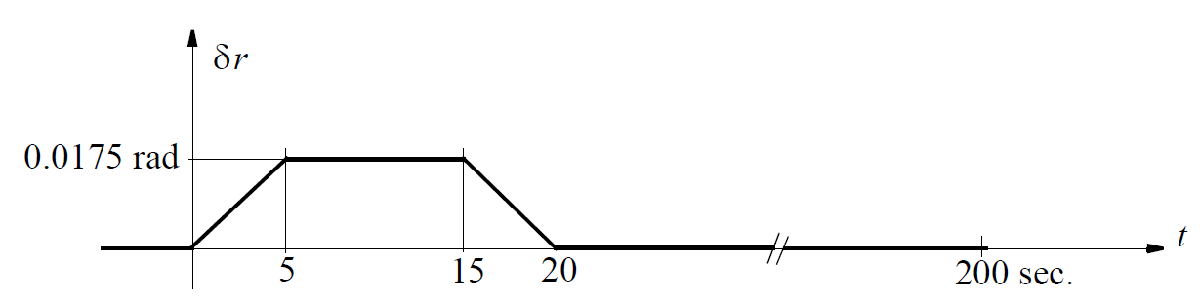

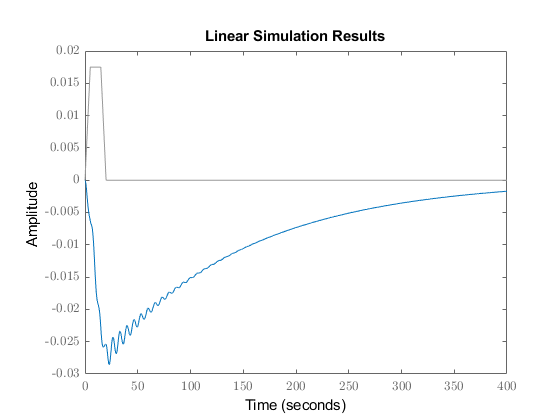

% Your solution goes here:
t = 0:0.1:400;

u1 = t(1:50)*0.0175/5;
u2 = t(51:150)*0+0.0175;
u3 = 0.0175-u1;
u4 = t(201:end)*0;
u = [u1 u2 u3 u4];

x0 = [0 0 0 0];

lsim(sys_ss,u,t,x0)